# Four-Wheel Mecanum

Copyright 2018-2019 The MathWorks, Inc.

## Kinematic Model

This vehicle has four Mecanum wheels which can all be driven independently. Since there are 4 inputs and 3 degrees of freedom, the system is overactuated.

Reference: [http://research.ijcaonline.org/volume113/number3/pxc3901586.pdf](http://research.ijcaonline.org/volume113/number3/pxc3901586.pdf)

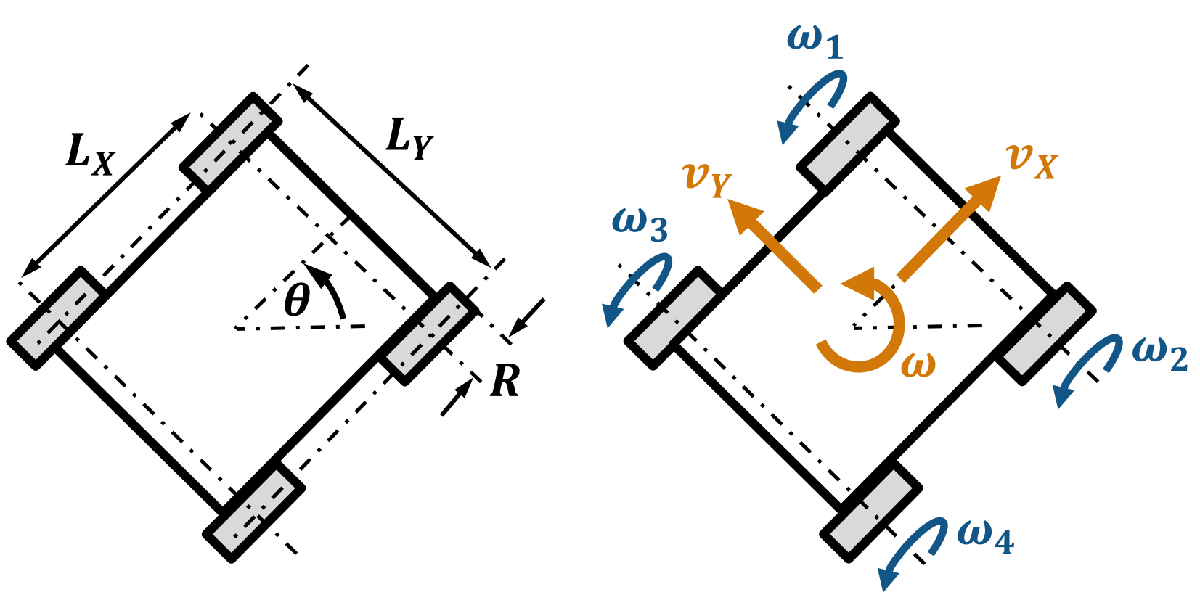

**Inputs:**

- Wheel speeds $\left\lbrack \omega_1 \ ;\omega_2 \ ;\omega_3 \;;\omega_4 \right\rbrack$, in rad/s

**Outputs**

- Linear velocities$v_X$ and $v_Y$, in m/s

- Angular velocity $\omega$, in rad/s

**Forward Kinematics**

The forward kinematics can be expressed in matrix form as follows.


$${\left[\begin{array}{c}
v_X \\
v_Y \\
\omega 
\end{array}\right]}=\frac{R}{4}{\left[\begin{array}{cccc}
1 & 1 & 1 & 1\\
-1 & 1 & 1 & -1\\
-2/\left(L_X +L_Y \right) & 2/\left(L_X +L_Y \right) & -2/\left(L_X +L_Y \right) & 2/\left(L_X +L_Y \right)
\end{array}\right]}{\left[\begin{array}{c}
\omega_1 \\
\omega_2 \\
\omega_3 \\
\omega_4 
\end{array}\right]}\ \ \$$


**Inverse Kinematics**

The inverse kinematics can be expressed in matrix form as follows.


$${\left[\begin{array}{c}
\omega_1 \\
\omega_2 \\
\omega_3 \\
\omega_4 
\end{array}\right]}\ \ =\ {\left[\begin{array}{ccc}
1 & -1 & -\left(L_X +L_Y \right)/2\\
1 & \mathrm{\ }\mathrm{\ }\mathrm{\ }1 & \ \ \ \left(L_X +L_Y \right)/2\\
1 & \ \ \ 1 & -\left(L_X +L_Y \right)/2\\
1 & -1 & \ \ \ \left(L_X +L_Y \right)/2
\end{array}\right]}{\left[\begin{array}{c}
v_X \\
v_Y \\
\omega 
\end{array}\right]}$$


## MATLAB Usage

Create a `FourWheelMecanum` object

wheelRadius = 0.1;  % Wheel radius [m]
wheelBase = 0.4;    % Wheelbase [m]
wheelTrack = 0.5;   % Wheel track [m]
vehicle = FourWheelMecanum(wheelRadius,wheelBase,wheelTrack)

vehicle =   FourWheelMecanum with properties:

    wheelRadius: 0.1000
      wheelBase: 0.4000
     wheelTrack: 0.5000

Solve forward kinematics

w = [1; 0; 0.5; -0.25]; % Wheel speeds [w1; w2; w3; w4]	
vel = forwardKinematics(vehicle,w)

vel =     0.0313
   -0.0063
   -0.0972

Solve inverse kinematics

velRef = [-0.5; 0.25; 1]; % Body speeds [vx; vy; w]
w = inverseKinematics(vehicle,velRef)

w =    -12
     2
    -7
    -3

Get the forward and inverse kinematics matrices

M = getForwardMatrix(vehicle)

M =     0.0250    0.0250    0.0250    0.0250
   -0.0250    0.0250    0.0250   -0.0250
   -0.0556    0.0556   -0.0556    0.0556

Minv = getInverseMatrix(vehicle)

Minv =    10.0000  -10.0000   -4.5000
   10.0000   10.0000    4.5000
   10.0000   10.0000   -4.5000
   10.0000  -10.0000    4.5000

Change a parameter and update the kinematics matrices. Rerun the previous section to see the different matrices.

vehicle.wheelRadius = 0.05;
computeMatrices(vehicle);

Reference examples:

- [Discrete-time kinematic simulation](matlab:edit mrsMecanumDiscrete)

- [Continuous-time kinematic simulation](matlab:edit mrsMecanumContinuous)

## Simulink Usage

Simulink blocks are in the **Kinematic Models > Four-Wheel Mecanum** section of the [block library](matlab:mobileRoboticsLib).

- Use the **Four-Wheel Mecanum Forward Kinematics** and **Four-Wheel Mecanum Inverse Kinematics** blocks to convert between body velocities and wheel velocities.

- Use the **Four-Wheel Mecanum Simulation** block to simulate the pose given wheel speeds as inputs. You can configure the initial pose and simulation sample time.

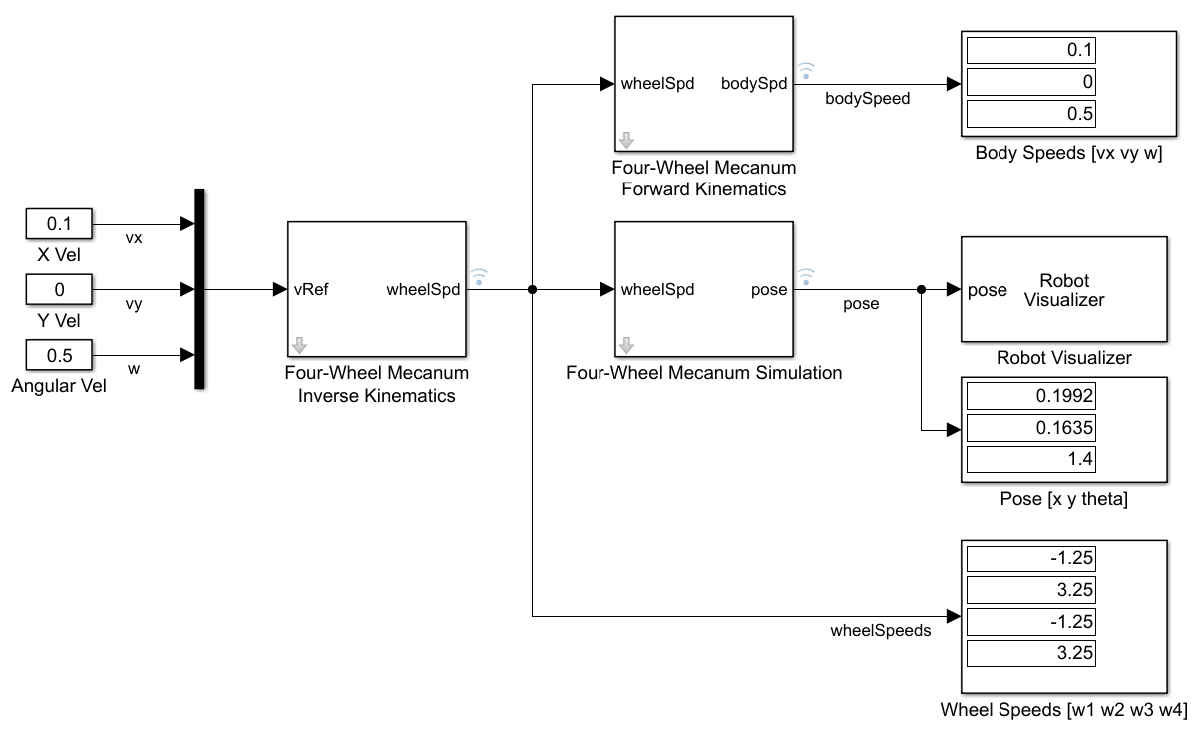

Reference example:

- [Four-wheel mecanum kinematic simulation](matlab:mrsMecanumModel)